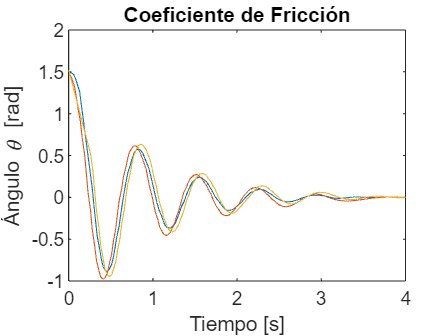

% Se cargan los datos obtenidos experimentalmente
load("FrictionCoef.mat")

% Se gráfican estos datos
figure()
plot(time1,theta1);
hold on
plot(time2,theta2);
plot(time3,theta3);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

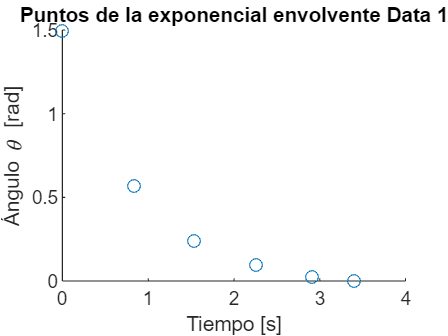


%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks1p,locs1p] = findpeaks(theta1,time1);
[pks1n,locs1n] = findpeaks(-theta1,time1);
pks1 = [theta1(1,1); pks1p];
locs1 = [time1(1,1); locs1p];


%Se gráfican los picos
figure()
scatter(locs1,pks1);
title('Puntos de la exponencial envolvente Data 1')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

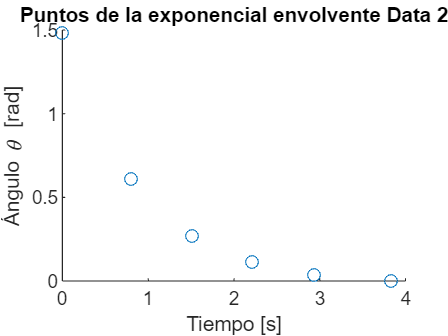


%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks2p,locs2p] = findpeaks(theta2,time2);
[pks2n,locs2n] = findpeaks(-theta2,time2);
pks2 = [theta2(1,1); pks2p];
locs2 = [time2(1,1); locs2p];

%Se gráfican los picos
figure()
scatter(locs2,pks2);
title('Puntos de la exponencial envolvente Data 2')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

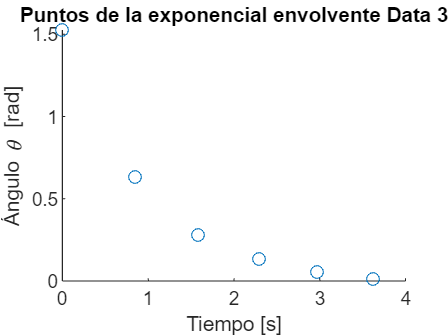



%Se encuentran los máximos y mínimos locales de la función teniendo en
%cuenta que no almacenará el primer valor de la función por lo que debe ser
%añadido

[pks3p,locs3p] = findpeaks(theta3,time3);
[pks3n,locs3n] = findpeaks(-theta3,time3);
pks3 = [theta3(1,1); pks3p];
locs3 = [time3(1,1); locs3p];

%Se gráfican los picos
figure()
scatter(locs3,pks3);
title('Puntos de la exponencial envolvente Data 3')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')


envolvente1 = @(t) ((pi/2)*exp(-1.3*t))

envolvente1 = function_handle with value:
    @(t)((pi/2)*exp(-1.3*t))


envolvente2 = @(t) ((pi/2)*exp(-1.2*t))

envolvente2 = function_handle with value:
    @(t)((pi/2)*exp(-1.2*t))


envolvente3 = @(t) ((pi/2)*exp(-1.18*t))

envolvente3 = function_handle with value:
    @(t)((pi/2)*exp(-1.18*t))


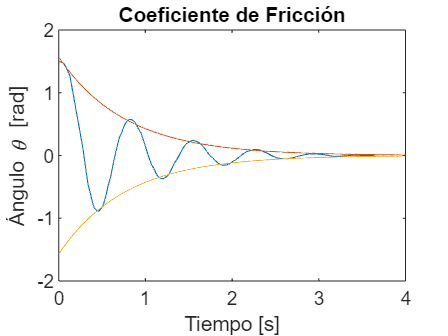

time = linspace(0,4,1000);

e1 = envolvente1(time);
e2 = envolvente2(time);
e3 = envolvente3(time);


% Se gráfican las funciones obtenidas
figure()
plot(time1,theta1);
hold on
plot(time,e1);
plot(time,-e1);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

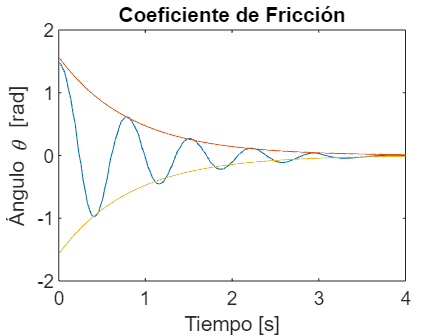


figure()
plot(time2,theta2);
hold on
plot(time,e2);
plot(time,-e2);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')

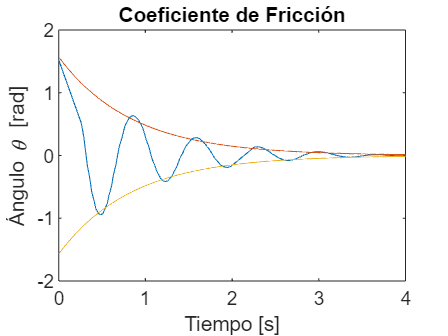


figure()
plot(time3,theta3);
hold on
plot(time,e3);
plot(time,-e3);
hold off
title('Coeficiente de Fricción')
xlabel('Tiempo [s]')
xlim([0,4])
ylabel('Ángulo \theta [rad]')